# Slewing jib crane derivation with analytical dynamics approach

This script is a functionalized method to derive equations of motion via Lagrange's Equation with use of the Symbolic Toolbox.

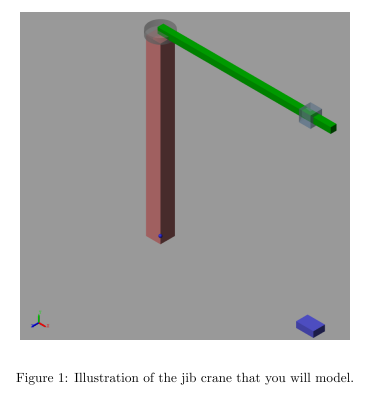

% cleanup
% clc,clear,close all
sympref('default');         % cleanup symbolic preferences
sympref('MatrixWithSquareBrackets',true);

## Problem Setup

For the remainder of this script, methods for dynamic systems without constraints will be shown. Methods shown here are extended for systems with constraints and the topic of constraint stabilization also become relevant.


$$\frac{d}{dt}\left(\frac{\partial L}{\partial \dot{q}_i}\right) - \frac{\partial L}{\partial q_i} = Q_i 
\; \;, \; \; 
i = 1,...,n$$


Lagrange's equation without constraints.

- $L$: The Lagrangian, L = T - V where T is kinetic energy and V is potential energy of the system.

- $q_i$: The $i^{th}$ generalized coordinate (coordinate index).

- $Q_i$: The $i^{th}$ generalized force (the $i^{th}$ externally applied non-conservative force).

The equation shown above is quite loaded with meaning and will be the last step of this derivation process. In order to get there, position and velocity vectors will be defined based on the generalized coordinates chosen, the Lagrangian will be formed, and generalized forces will be computed. After these things, all that will be needed is some plug and chug to extract the equations of motion. As a bonus step with the Mathworks package being used, the equations of motion can be generated into functions for implementation in Simulink.

### Parameters and Generalized Coordinates

Now let's get started!

% specify the generalized coordinates and their time and symbolic versions
% q1: psi_1     (rad)       motor/jib slew
% q2: h         (m)         hoist length
% q3: L         (m)         trolley position
% q4: psi_3     (rad)       load Rz angle
% q5: theta_3   (rad)       load Ry angle
% q6: phi_3     (rad)       load Rx angle

% generate the variables for the generalized coordinates. Put prescribed
% variables at the beginning for easier indexing
syms psi_1 h L psi_3 theta_3 phi_3
genGenCoords([psi_1,h,L,psi_3,theta_3,phi_3])

% define other variables
t  = sym('t' ,'real');          % (sec)     time
g  = sym('g' ,'real');          % (m/s^2)   gravitational acceleration
m  = sym('m','real');           % (kg)      load mass
w  = sym('w','real');           % (m)       jib to attachment point width
wd = sym('wd','real');          % (m)       load width
Ixx = sym('Ixx','real');        % (kg-m^2)  mass moments of inertia
Iyy = sym('Iyy','real');
Izz = sym('Izz','real');

### Position and Velocity Vectors with Rotation Matrices

Rotation Matrices

Single axis rotation matrices look like the following. These will be use to develop the specific rotation matrices for a chose sequence.


$$R_x(\alpha) = \left[ \matrix{1 & 0 & 0 \cr 0 & \cos(\alpha) & \sin(\alpha) \cr 0 & -\sin(\alpha) & \cos(\alpha) }\right]$$

$$R_y(\alpha) = \left[ \matrix{\cos(\alpha) & 0 & -\sin(\alpha) \cr 0 & 1 & 0 \cr \sin(\alpha) & 0 & \cos(\alpha) }\right]$$

$$R_z(\alpha) = \left[ \matrix{\cos(\alpha) & \sin(\alpha) & 0 \cr -\sin(\alpha) & \cos(\alpha) & 0 \cr 0 & 0 & 1 }\right]$$


% fundamental rotation matrices
syms ang psi theta phi
Rx = [ 1  0        0
       0  cos(ang) sin(ang)
       0 -sin(ang) cos(ang) ];

Ry = [ cos(ang) 0 -sin(ang)
       0        1  0
       sin(ang) 0  cos(ang) ];
  
Rz = [ cos(ang) sin(ang) 0
      -sin(ang) cos(ang) 0
       0        0        1 ];

#### Rotation matrices used

Two rotation matrices are used 1) for the slewing jib 2) for the attachment point of the load.

RJLz = subs(Rz,ang,psi_3);
RJLy = subs(Ry,ang,theta_3);
RJLx = subs(Rx,ang,phi_3);
RJL  = RJLz * RJLy * RJLx;                  % 1-2-3 rotation sequence
RLJ = RJL';

RIJ = subs(Rz,ang,psi_1);
RJI = RIJ';

RLI = RJI * RLJ;
RIL = RLI';

#### Extract angular velocity from rotation matrices

Using the rotation matrix from the load frame to inertial frame, a spin tensor can be developed to extract absolute angular velocity of the load in the load frame.

RLI      = subs(RLI,varS,varT);
RLId     = diff(RLI,t);
RLId     = subs(RLId,varT,varS);
OMGL_I_L = RIL * RLId;
OMGL_I_L = simplify(subs(OMGL_I_L,varT,varS));
omgL_I_L = [OMGL_I_L(3,2);OMGL_I_L(1,3);OMGL_I_L(2,1)];

#### Position

There are many different ways that variables can be represented in programming like this but the important aspect of these definitions is that they are unambigious and readable. A suggested notation for variable definitions for the proceeding sections goes like this:

A vector can be written like $r_{c_{ik}}$ (rc_i_k for program syntax).

- $r$: The type of vector. In this case could be position.

- $c$: The location type of vector. In this case could be centroid. Other example could be force location ($f$) or other interesting points.

- $i$: The relative location (the relative point that the previous subscript is referring to).

- $k$: The frame index (represented in the $k$ frame).

r3_1_J = [L;0;-w];                  % 3 relative to 1 in J frame
rp_3_L = [0;0;-h-wd/2];             % p relative to 3 in L frame
rp_I_L = RJL * r3_1_J + rp_3_L;     % absolute of p in L frame

But we also want the absolute position vector of p in the inertial frame for potential energy and the absolute velocity vector.

rp_I_I = simplify(subs(RLI * rp_I_L,varT,varS));    % absolute of p in the inertial frame

#### Velocity

Now is the time to differentiate for an absolute position vector.

rp_I_I = subs(rp_I_I,varS,varT);    % subs for derivative
vp_I_I = diff(rp_I_I,t);            % derivative
vp_I_I = subs(vp_I_I,varT,varS);    % absolute velocity in the inertial frame

### Form the Energy Terms for the Lagrangian

I = diag([Ixx Iyy Izz]);                % inertia matrix
T = 1/2 * m * (vp_I_I' * vp_I_I) + ...
    1/2 * (omgL_I_L' * I * omgL_I_L);   % (J) kinetic energy
V = m * g * (rp_I_I' * [0;0;1]);        % (J) potential energy

% Lagrangian
Lag = T - V;

### Generalized Forces

To form the generalized force we perform $\vec{F} \cdot \vec{v}$ and extract the coefficients in front of the first time derivatives of the generalized coordinates.

num = size(varS,1);                                         % number of generalized coordinates
varDEQ = varS(4:num,:);                                     % variables used for DEQs. skip the prescribed motion for DEQs
Qi = genGenForces(0,0,varS(4:num,:),varT(4:num,:));    % generate the generalized forces

### Final Equations of Motion

[MM1,FF1] = lagrangeEQNS(Lag,Qi,varDEQ,varS,varT);              % compute lagrange's equation
sympref('default');         % cleanup symbolic preferences